% Initialize and load in images
clc; close all

% resin for comparision
% place filepath containing images here: each use the following naming
% scheme
cd '/Users/dreyton/Desktop/Butterfly Images 2/50_0.06Shell'

% P1
I0 = imread('P1 - P2 OFF.png');
I0 = rgb2gray(I0);

I1 = imread('P1 - BOTH ON.png');
I1 = rgb2gray(I1);

% P2
I2 = imread('P2 - P1 OFF.png');
I2 = rgb2gray(I2);

I3 = imread('P2 - BOTH ON.png');
I3 = rgb2gray(I3);


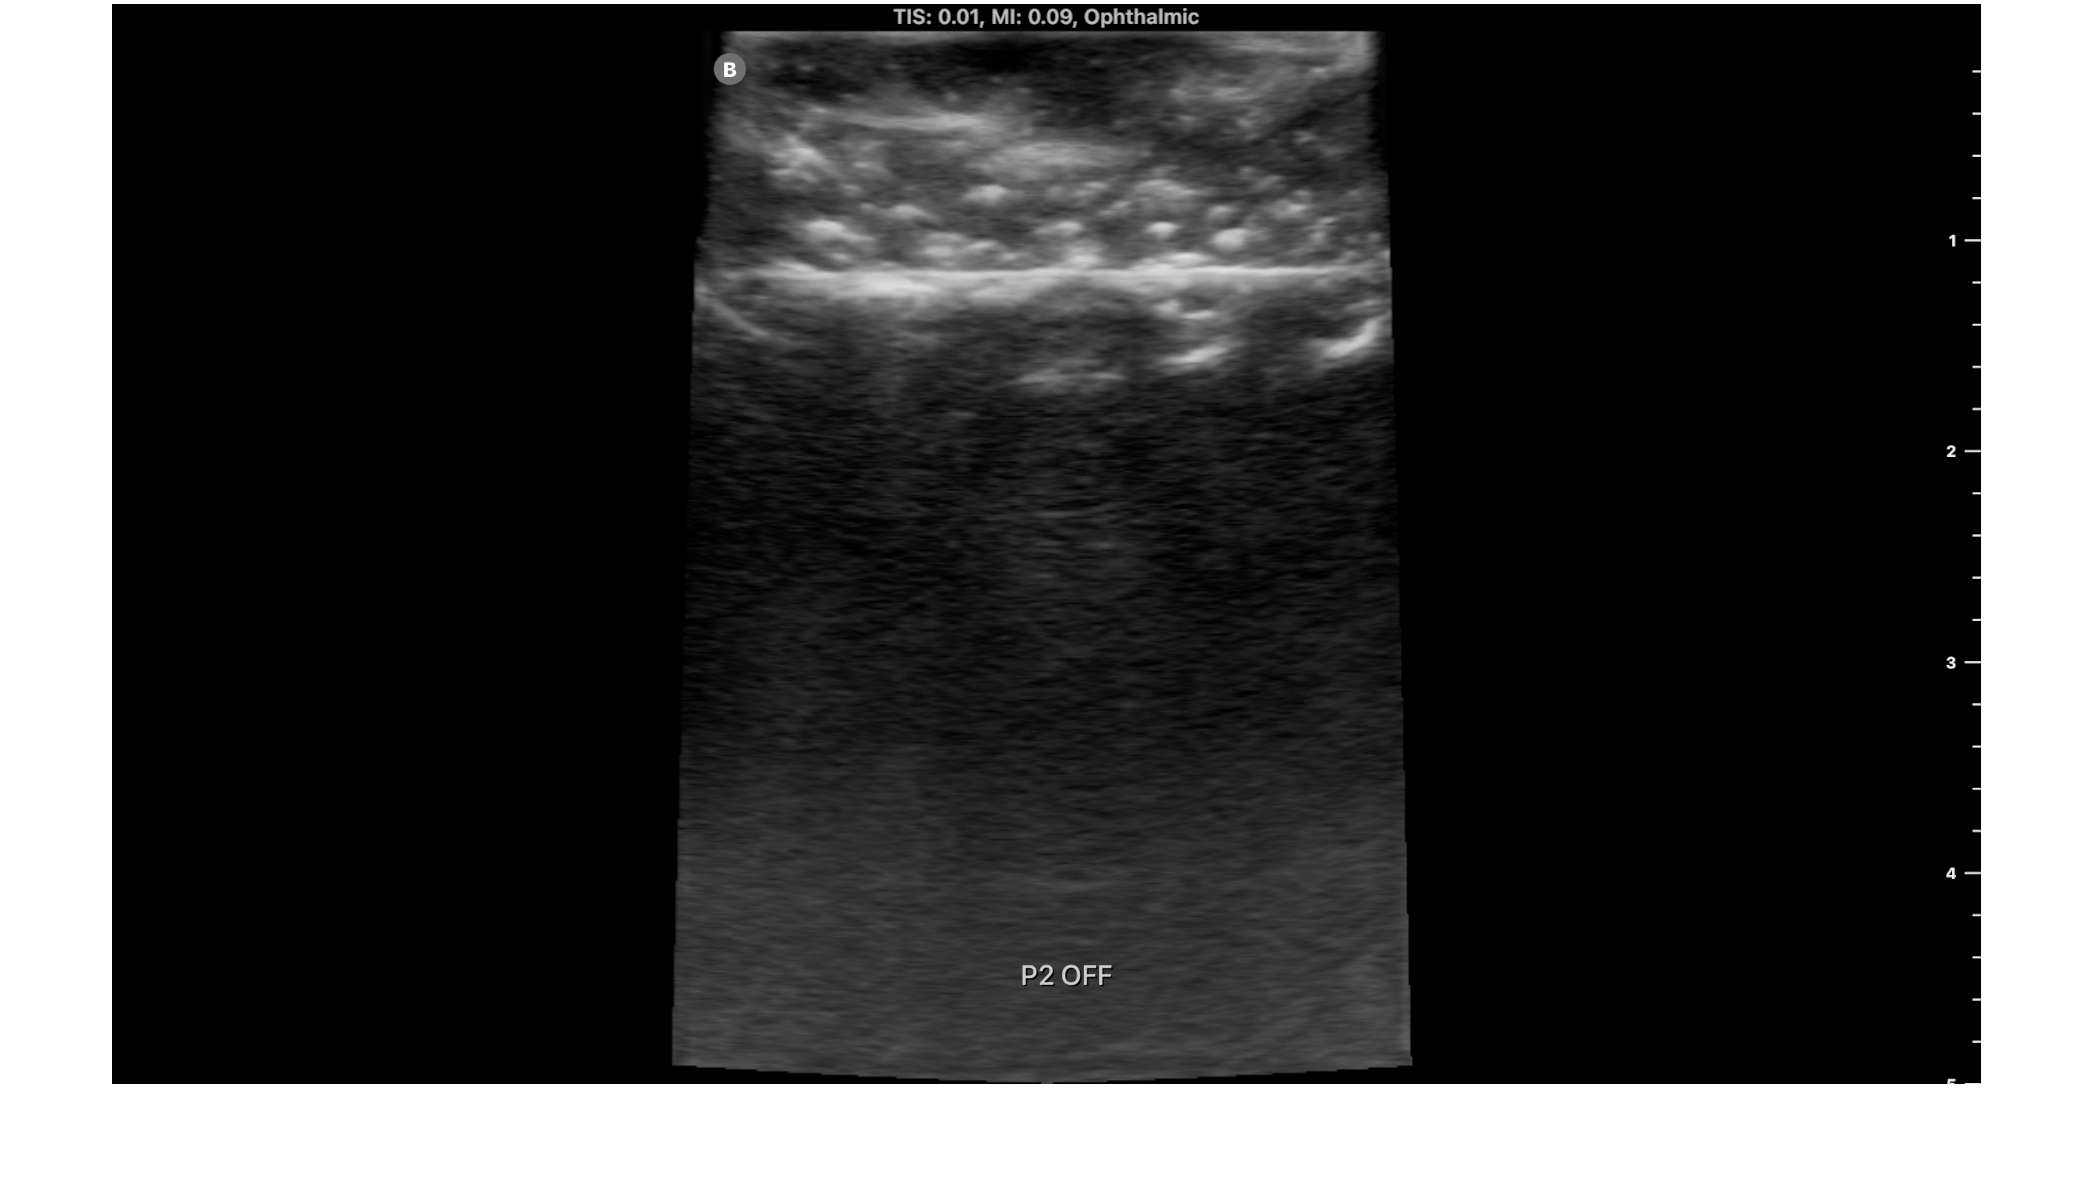

% Initial crop of first image, u
% u = one on, one off (from probe 1)
imshow(I0)

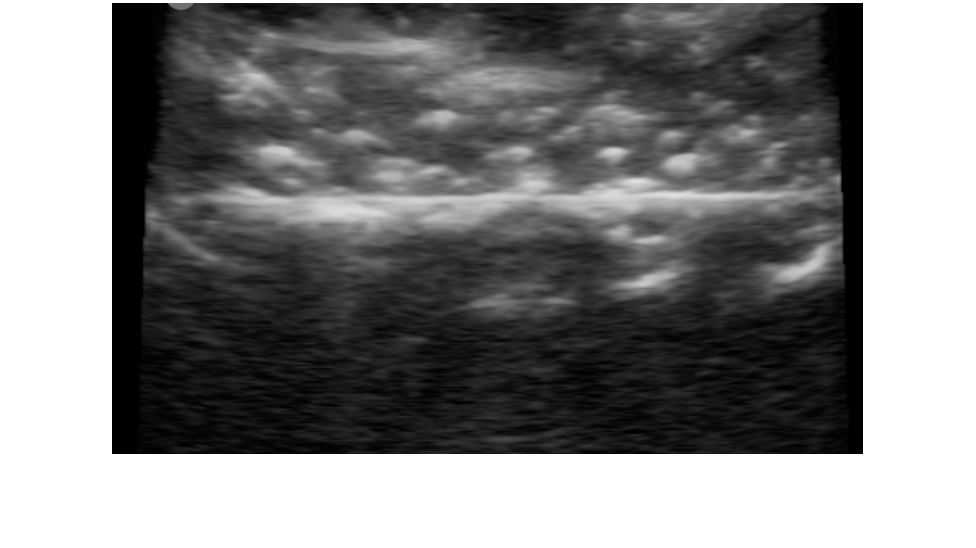

img_region = [550 75 750 450];
u = imcrop(I0,img_region);
imshow(u)

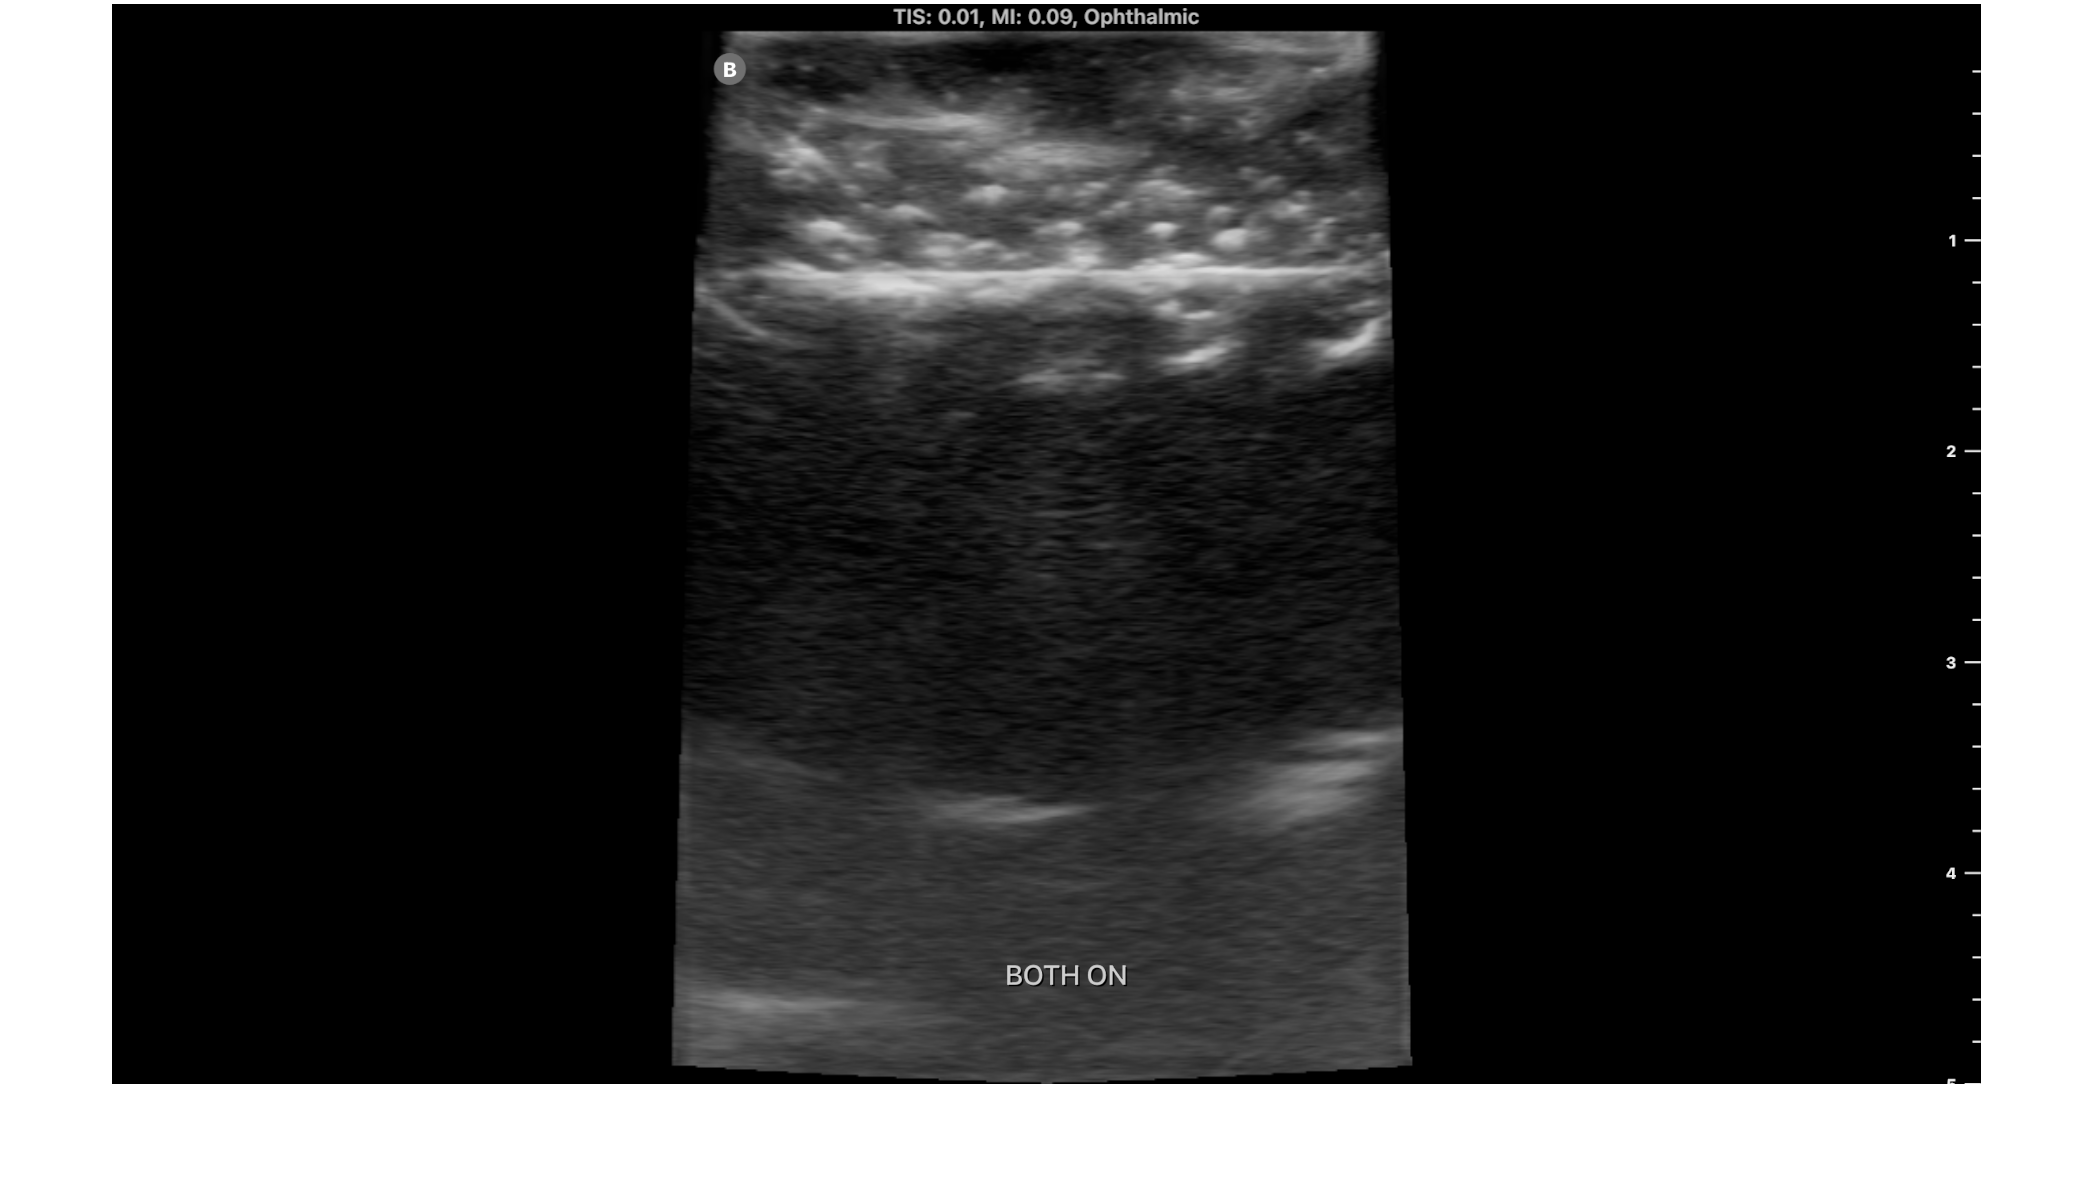

% crop of second image, v
% v = BOTH ON (from probe 1)
imshow(I1)

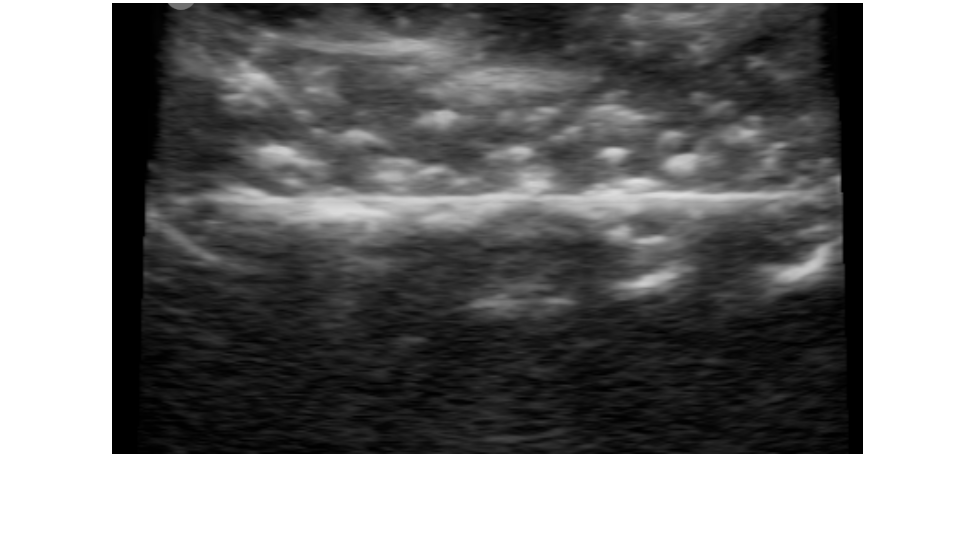

v = imcrop(I1,img_region);
imshow(v)

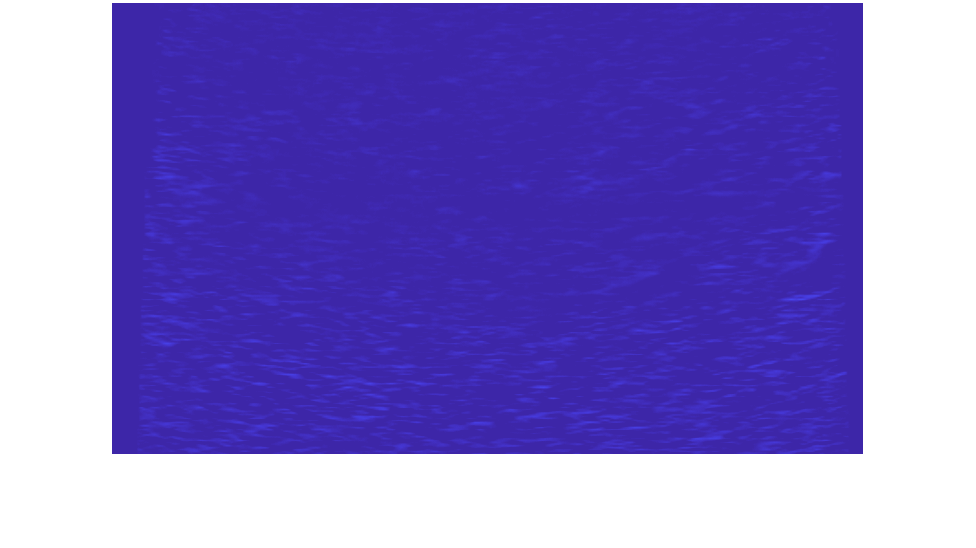

% u - v = diff
diff = imsubtract(u, v);
imshow(diff, "Colormap",parula) % this colormap can highlight signal in image


max(diff(:))

ans = uint8
29

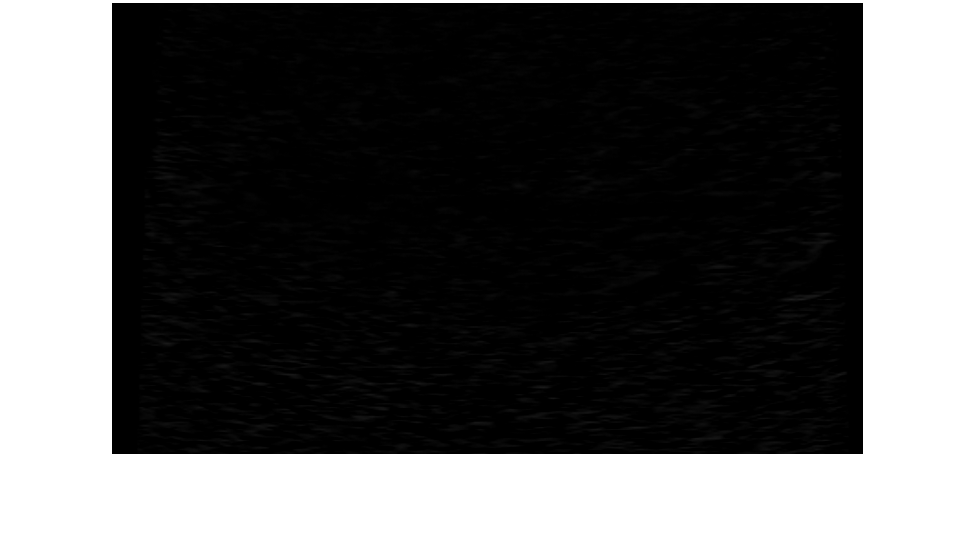

%diff = uint8(255*mat2gray(diff));
imshow(diff);

ans = uint8
29

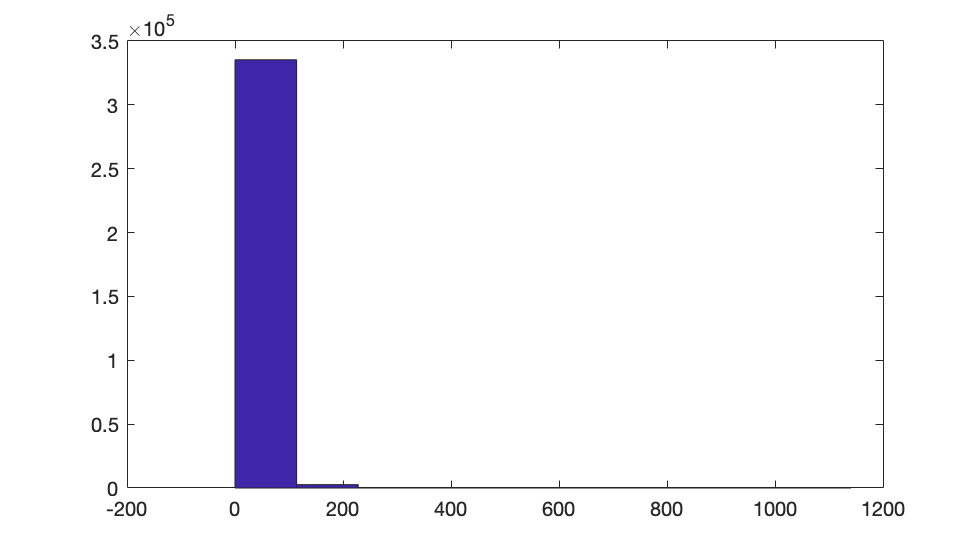

max(diff(:))

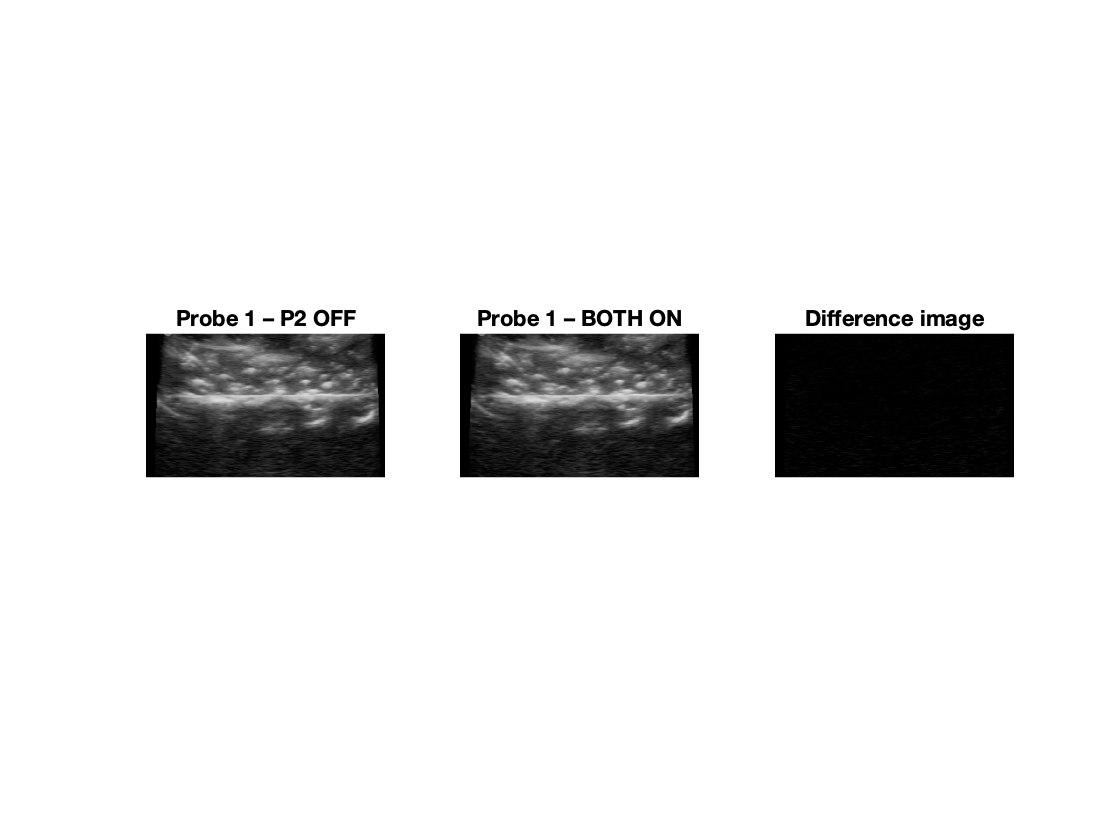

figure
subplot(1,3,1)
imshow(u)
title('Probe 1 – P2 OFF')

subplot(1,3,2)
imshow(v)
title('Probe 1 – BOTH ON')

subplot(1,3,3)
imshow(diff)
title('Difference image')

clear figure


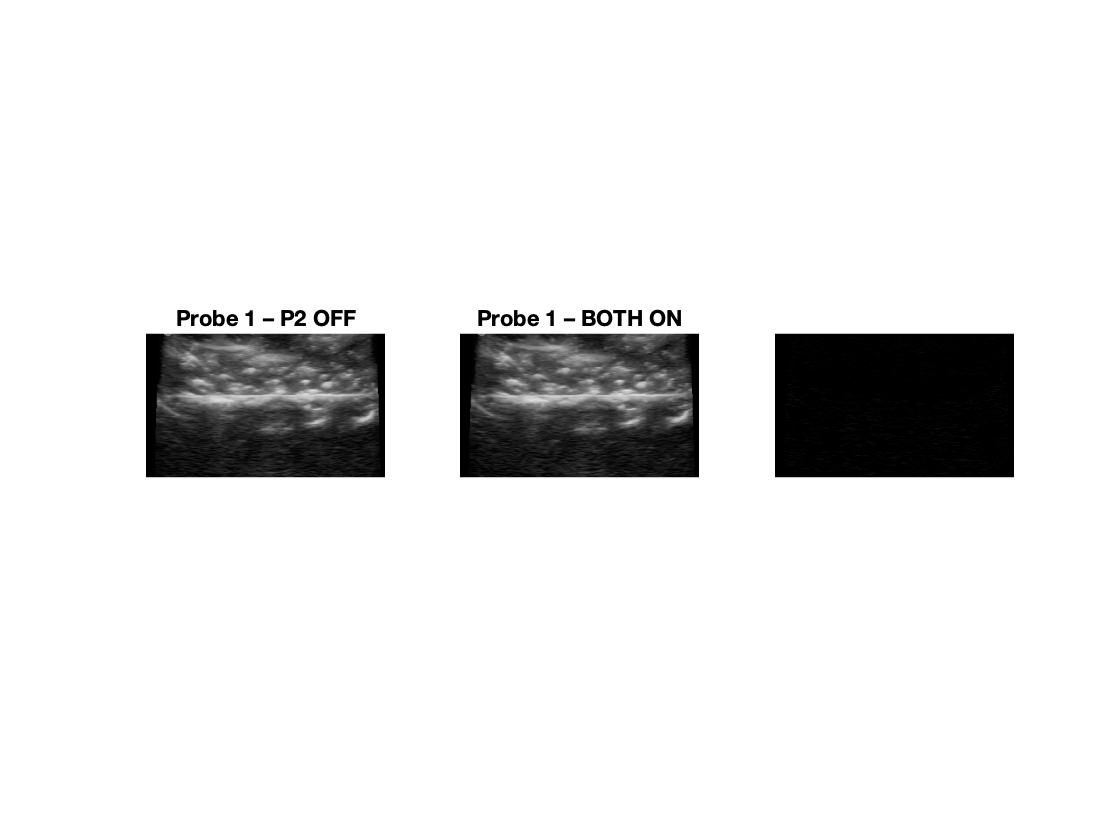

% compare to image on other side

i2 = imcrop(I2, img_region);
imshow(i2)
title('From other side')

i3 = imcrop(I3, img_region);
imshow(i3)
title('From other side')

diff2 = imsubtract(i2, i3);

imshow(diff2)

% Summary of difference signal - sum and mean
disp('Attenuated Signal Sum')

Attenuated Signal Sum


P1_A = sum(diff(:))

P1_A = 471421

P2_A = sum(diff2(:))

P2_A = 265331

disp('  ')

disp('Attenuated Signal Avg')

Attenuated Signal Avg


P1_mean = mean2(diff(:))

P1_mean = 1.3919

P2_mean = mean2(diff2(:))

P2_mean = 0.7834

% Summary of original signal - sum and mean
disp('Original Signal Sum')

Original Signal Sum


P1_A0 = sum(u(:))

P1_A0 = 20011127

P2_A0 = sum(i2(:))

P2_A0 = 17371942

disp('  ')

disp('Original Signal Avg')

Original Signal Avg


P1_A0_avg = mean2(u(:))

P1_A0_avg = 59.0820

P2_A0_avg = mean2(i2(:))

P2_A0_avg = 51.2899

% Distribution of the signals
figure
x = double(diff(:))
% 
hist(x')

% Take the Fourier transform to analyze the frequency components of
% resultant signal - may not be very necessary
y = fft(diff);
idx = diff >= 0; %filter out 0 values
hist(y(idx))